# LECTURE WEEK VI. - HANDS-ON

# FREQUENCY RESPONSE OF FILTERS & CONVOLUTION USING DTFT/DFT

**Objectives:**

- Compute and visualize the transfer function of an FIR filter using the DFT.

- Relation between DTFT and DFT of the transfer function.

- Implementing convolution using DFTs.

- Speed difference between convolution in the time domain and Fourier domain.

- Linear and circular convolutions.

- Designing the impulse response of an FIR filter by specifying its transfer function in the DFT domain.

## MATLAB HANDS-ON Assignment VI.1: FIR filter design

**Completion requirements:**

- Show the impulse responses as obtained in assignments ***A*** and ***B***. Discuss the similarities and differences you observe.

- Show and explain the frequency response plots for the different given values of K as requested in assignment ***C***. Explain how you selected the most important filter coefficients.

- Show the raised-­cosine windows for K=20 and N=128 as requested in assignment ***D***.

- Show the plotted results for assignment ***E***, and explain how these differ from those in assignment ***C***.

- Explain in at most five sentences how you solved assignment ***F***, and show the resulting frequency response plot.

The proper design of filter coefficients/impulse response is crucial for the success of discrete signal processing in a variety of applications. There is a wide range of design toolkits available, including several design tools in MATLAB

We here consider the simplest of all, which is the design of zero-phase FIR filters by specifying their frequency response. The terminology "zero-phase" means that all DFT coefficients of the frequency response are real-valued and hence their phase is zero. This leads to an FIR filter of which the impulse response is symmetric around n=0.

***A.***

We design a low-pass filter which ideally passes all frequencies smaller than $\pi / 2$. Because of required symmetry of the frequency response, the filter passes also all frequencies larger than $3\pi / 2$. For all other frequencies the response is "0", as illustrated in the sketch below.

 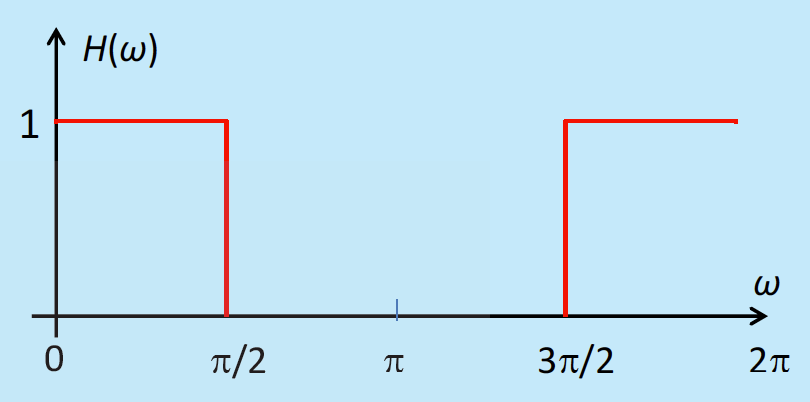

Create the discretized version of $H[k]$ of this frequency response in a vector of length $N=64$. Make sure that the (complex-conjugated) symmetry conditions of $H[k]$ are properly satisfied (see the instance Exercise V.3). Stem-plot the impulse response that you obtain after inverse DFT of $H[k]$. 

***Answer:***

How many non-zero coefficients does the FIR filter/impulse response have? 

***Answer:***

Is the impulse symmetric? 

***Answer:***

What is the symmetry point?

***Answer:***

***B.***

Repeat part A. with `N=512`. 

***Answer:***

How many non-zero coefficients does the FIR filter/impulse response have?

***Answer:***

The biggest problem with the approach in part ***A*** is that we obtain a very large number of small but still non-zero filter coefficients, which makes the implementation unattractive. Furthermore, filters created in this way create a lot of spurious "ripple" in filtered signals. For that reason we typically truncate the number of non-zero filter coefficients.

***C.***

Use the result in part ***B*** and keep only the most important $2K+1$ filter coefficients. In terms of the impulse response, this means that we keep $h[-K] \dots h[-1], h[0], h[1], \dots h[K]$, and set all other coeffients to zero. Figure out which filter coefficients to keep in the vector that you obtained in part ***B.*** Set all other values to zero. Then compute and plot the frequency response of the resulting FIR filter. Do this for K=1, 2, 5, 10, 20. 

***Answer:***

What effects do you observe?

***Answer:***

***D.***

One way of obtaining a better approximation to the desired frequency response of the low-pass filter in the above figure, is gradually pushing the remaining non-zero filter coefficients to zero. This can be achieved by multiplying the impulse response obtained in part ***B*** by the raised-cosine window.


$$w[n] = cos^{2}\Big(\frac{\pi}{2} \cdot \frac{n}{K+1}\Big) \quad -K\le{n}\le{K}$$


For use in MATLAB, circular extension of the window is needed, so that the window looks like this for K=9 and N=32.

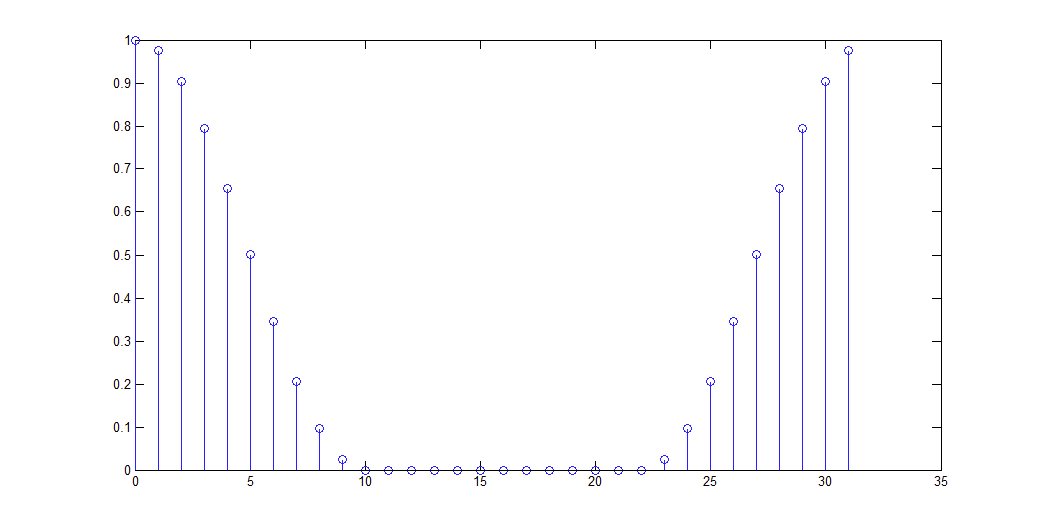

Implement a MATLAB function that creates the raised-cosine window, and show the result for K=20 and N=128.

***Answer:***

***E.***

Use the result in part ***B*** and multiply the impulse response with the raised-cosine window (`N=512`). Then compute and plot the frequency response of the resulting FIR filter. Do this for K=1, 2, 5, 10, 20. 

***Answer:***

What effects do you observe? Compare to plots in plot ***C***.

***Answer:***

***F.***

Design an FIR filter, i.e. find the impulse response, when the desired frequency response is given by the following figure. Determine an approapriate number of filter coefficients (2K+1). Also choose the DFT length (N) appropriately. Plot the frequency response of the FIR filter you have designed.

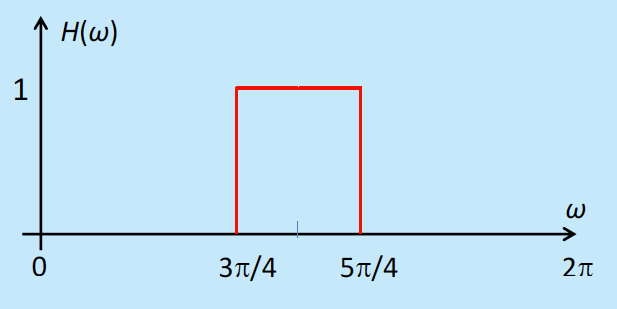

***Answer:***

**Completion requirements:**

- Show the impulse responses as obtained in assignments ***A*** and ***B***. Discuss the similarities and differences you observe.

- Show and explain the frequency response plots for the different given values of K as requested in assignment ***C***. Explain how you selected the most important filter coefficients.

- Show the raised-­cosine windows for K=20 and N=128 as requested in assignment ***D***.

- Show the plotted results for assignment ***E***, and explain how these differ from those in assignment ***C***.

- Explain in at most five sentences how you solved assignment ***F***, and show the resulting frequency response plot.

## MATLAB HANDS-ON Assignment VI.2: Step counter revisited

**Completion requirements:**

- Show the magnitude of the spectrum of the ideal walking signal in overlay with the transfer function of the FIR filter.

- Show a plot of the normalized signals in the (at least 4) segments.

- Show the filtered magnitude spectra of the segments as requested in part ***D*** and explain what detection rule you would apply as requested in part ***E***.

- (Optionally) Show the result of the complete detection algorithm as in part ***F***.

We reconsider the problem of counting steps addressed in Assignment IV.2. With the tools of Fourier analysis, we can now develop a system that distinguishes between walking and other movements based on the spectral content.

We first consider the ideal signal that would result if no degradations occur in the walking motion and if the walking is extremely smooth. The file “idealwalkingpattern.mat” contains such ideal signal, derived from the “ideal step” signal values listed in Assignment IV.2. The sampling frequency of the signal is 9.5 Hz.

***A.***

Compute the magnitude spectrum of this ideal walking pattern, visualize the result, and find the walking frequency (in steps per second). When visualizing spectra, use a proper frequency axis in Hertz, running from 0 Hz up to the sampling frequency.

***Answer:***

Based on this walking pattern, we can design a proper low pass filter to try to separate “walking” from “other movements”. The impulse response of the FIR filter (order 55) is given by the following coefficients (see file FIR55.txt)

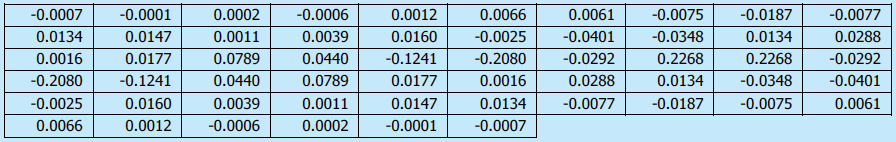

***B.***

Compute and visualize the transfer function. Overlay the transfer function on the result in part ***A*** – using the same (!) frequency scale.

***Answer:***

 Explain why this filter is indeed useful.

***Answer:***

We now consider the real walking signal, stored in the file “`data/walkingdata.mat`”. We will use the FIR filter to separate walking from other movements.

***C.***

Load the walking pattern and select at least four segments in the signal that have a clearly different signal wave form, that is, different types of movements. Use segment lengths of around 64 – 128 samples, use segments of the same length. In order to make the segments comparable, normalize the signals by first subtracting the mean and next normalize the signal’s variance to unity (=1). Then compute the magnitude spectrum of each segment and visualize the results in a single plot.

***Answer:***

***D.***

Filter each segment using the FIR filter in part ***B***. Execute the convolution by multiplying the DFT of the signal segment with the transfer function of the FIR filter (do NOT use the MATLAB convolution operation). Again, visualize the results after filtering in a single plot.

***Answer:***

***E.***

From the figure in part ***D*** you should be able to think of a way to discriminate walking from other movements. What is your proposal for such a detection rule?

***Answer:***

***F.***

If you have time left, you can implement the detection strategy proposed in part ***E***. Use the following algorithm structure that works with overlapping segments.

- N = 0 (start at the first sample).

- Extract *K* samples, starting at sample *N*.

- Compute the (magnitude of the) DFT of the segment. Filter the segment with the FIR filter as done in part ***D*** of this assignment.

- Apply the detection rule in part ***E*** on the segment, and decide if this segment contains a walking signal or some other movement.

- Increase *N* with a certain value, say between 1 and *K* (practical would be *K/4* or *K/2*). This is the starting point of the next generation.

- If *N + K* is larger than the length of the signal, we are done. Otherwise go to sep 2.

***Answer:***

Evaluate the result you obtain. How satisfied are you? Ideas for improvement? Other filter? Other detection rule? Other approach?

***Answer:***

**Completion requirements:**

- Show the magnitude of the spectrum of the ideal walking signal in overlay with the transfer function of the FIR filter.

- Show a plot of the normalized signals in the (at least 4) segments.

- Show the filtered magnitude spectra of the segments as requested in part ***D*** and explain what detection rule you would apply as requested in part ***E***.

- (Optionally) Show the result of the complete detection algorithm as in part ***F***.